# Script: Protocol Data Visualization

1) Implements a rapid visualization workflow for electrophysiology current‑clamp datasets.

2) Aggregates spontaneous firing, evoked activity, and sag voltage protocols into a unified analysis pipeline.

3) Enables fast exploratory inspection and comparison across multiple recording sessions.

4) Supports streamlined data review prior to preprocessing, feature extraction, or statistical modeling.

%% 1. Project: Cerebellar Purkinje cell current-clamp recordings (p84-p98).
% CODE for Data Visualization: Spontaneous firing, Evoked Spiking (300pA & 700pA), & Voltage Sag
% Script Update: 6.13.2024 by Fernando Isaac Guillen
clear;clc;

%% 2.Select experiment (excel file) & cell (spreadsheet) 
Experiment = num2str('Exp19.xlsx');      % Select experiment number (excel file)
Cell = num2str('Cell 1');                % Select cell number (spreadsheet)

RecordedCells = sheetnames(Experiment);  % Return recorded cells in the experiment
  disp(['Experiment: ',Experiment]);

Experiment: Exp19.xlsx


  disp(RecordedCells);

Cell 1


  disp(['Analyzing: ', Cell]);

Analyzing: Cell 1



%% 3.Import data from excel into matlab
CellData = readmatrix(Experiment,'Sheet',...
    Cell,'Range','');           % Imports data from selected excel file & spreadsheet 

%% Mouse info: Genotype & Age
GenoType= CellData(1,1);        % Return mouse genotype:'1= WT' or '2= KO'
Age = CellData(1,2);            % Return mouse age (weeks)
if GenoType == 1
    disp('Genotype: WT mouse');
    disp(['Mouse age: ',num2str(Age),' weeks']);
    Mouse = ('Wild Type');
elseif GenoType == 2
        disp('Genotype: KO mouse');
        disp(['Mouse Age: ',num2str(Age),' weeks']);
        Mouse = ('Knockout');
end

Genotype: WT mouse


Mouse age: 13.4 weeks


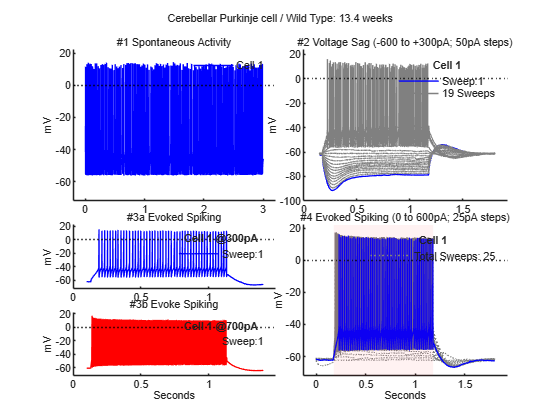


                    %% 4.Spontaneous firing protocol 
                    %  CC: GapFree 20sec (10kHz SR)

% Assign values to variables               
try
Time1 = CellData(3:30000,1);     % Time(ms)
x1 =Time1/1000;                % x1 = Convert ms to seconds
GapFree = CellData(3:30000,2);   % GapFree raw data

if isnan(GapFree)
    clear Time1 x1 GapFree
    disp('Missing Data: Purkinje Cell Spontaneous Firing Activity');
end
catch
    disp('Missing Data: Purkinje Cell Spontaneous Firing Activity');
end

% Figure. GapFree: Spontaneous Firing
figure;
subplot(4,4,[1 2 5 6]);

try
    plot(x1,GapFree,'b');
    yline(0,':k');
    axis padded
    ylabel('mV');
    ylim ([-72 22]);
%     xlabel('Seconds');
    legend(Cell, 'box', 'off');
    title('','#1 Spontaneous Activity');
    grid off;
    box off;
catch
    title('','Spontaneous Activity - NO DATA!');   
end

               %% 5. Evoked spiking protocol (holding cell to -65mV) 
                    % CC: 0 to 600pA; 1sec (20kHz)

% Assign values to variables 
Time3 =CellData(3:end,31);           % Time(ms)
x3 =Time3/1000;                      % x3= Convert ms to seconds
PC_Holding =CellData(3:end,32:56);   % Protocol: 'Holding cell'    

try
if isnan(PC_Holding)
    clear Time3 x3 PC_Holding
    disp('Missing Data: Evoke spiking(holding current)');
end
catch
    disp('Missing Data: Evoke spiking(holding current)');
end 

% Figure. HOLDING CELL PROTOCOL

subplot(4,4,[11 12 15 16]);
Sweep = 13;

try
    plot(x3,PC_Holding,'color',[0.5 0.5 0.5],'LineStyle',':');  
    hold on;
    plot(x3,PC_Holding(:,Sweep),'b','linewidth',1);
    yline(0,':k');
    xlim padded
    ylim ([-72 22]);
    xlabel('Seconds');
    ylabel('mV');
    grid off;
    box off;
    
    % Patch area of spikes in figure (pink color)
    x_points =[0.1782, 0.1782, 1.18, 1.18];
    y_points =[-82, 35, 35, -82];
    color = 'r';
    hold on;
    a = fill(x_points, y_points, color);
    a.FaceAlpha = 0.05;
    a.EdgeAlpha = 0;
    
    % Legend
    str1 = sprintf('Total Sweeps: 25');  
    lgd = legend(str1,'Box','off');
    title(lgd,Cell);
    title('','#4 Evoked Spiking (0 to 600pA; 25pA steps)');
    
catch
    title('','Evoked Spiking (0 to 600pA; 25pA steps) NO DATA!');   
end

        %% 6.Evoked spiking protocol (holding cell to -65mV)
                % CC: 300pA step; 1 sec (50kHz)

% Assign values to variables 
try
Time4 =CellData(3:end,58);      % Time(ms)
x4 =Time4/1000;                 % x4= Convert ms to seconds
pA300 =CellData(3:end,59:61);   % Protocol: 300pA step 

if isnan(pA300)
    clear Time4 x4 pA300
    disp('Missing Data: Evoke Spiking @300pA');
end
catch
    disp('Missing Data: Evoke Spiking @300pA');
end

% Figure. EVOKE SPIKING @300pA step
Sweep300pA = 1;

subplot(4,4,[9 10]);
try
    plot(x4,pA300(:,Sweep300pA),'b','linewidth',1);  
    hold on;
%     plot(x4,pA300,'color',[0.5 0.5 0.5],'LineStyle','-.');
    yline(0,':k');
    xlim padded
    ylim ([-72 22]);
%     xlabel('Seconds');
    ylabel('mV');
    grid off;
    box off;
        
    % Legend
    str1 = ['Sweep:',num2str(Sweep300pA)];
    str2 = ('');
    lgd = legend(str1,str2,'Box','off');
    title(lgd,[Cell, ' @300pA']);
    title('','#3a Evoked Spiking');
    
catch
    title('','Evoked Spiking @300pA - NO DATA!');   
end

% Figure. EVOKE SPIKING @700pA step
try
Time5 =CellData(3:end,4);       % Time(ms)
x5 =Time5/1000;                 % x5= Convert ms to seconds
pA700 =CellData(3:end,5:7);     % Protocol: 700pA step dep

if isnan(pA700)
    clear Time5 x5 pA700
    disp('Missing Data: Evoked Spiking @700pA');
end
catch
    disp('Missing Data: Evoked Spiking @300pA');
end            
Sweep700pA = 1;

subplot(4,4,[13 14]);
xlabel('Seconds');
try
    plot(x4,pA700(:,Sweep700pA),'r','linewidth',1);  
    hold on;
%     plot(x4,pA700,'color',[0.5 0.5 0.5],'LineStyle','-.');
    yline(0,':k');
    xlim padded
    ylim ([-72 22]);
    xlabel('Seconds');
    ylabel('mV');
    grid off;
    box off;
        
    % Legend
    lgd = legend(str1,str2,'Box','off');
    title(lgd,[Cell, ' @700pA']);
    title('','#3b Evoke Spiking');
    
catch
    title('','Evoke Spiking @700pA - NO DATA!');   
end

                   %% 7. Voltage Sag protocol 
              % CC: -600 to 300pA in 50pA Steps (10kHz SR)

% Assign values to variables 
try
Time6 =CellData(3:36000,63);    % Time(ms)
x6 =Time6/1000;                 % x5= Convert ms to seconds
Sag =CellData(3:36000,64:88);   % Protocol: 300pA step dep  

if isnan(Sag)
    clear Time6 x6 Sag
    disp('Missing Data: Sag voltage');
end
catch
    disp('Missing Data: Sag voltage');
end

subplot(4,4,[3 4 7 8]);
SweepSag = 1;
try
    plot(x6,Sag(:,SweepSag),'b','linewidth',1);  
    hold on;
    plot(x6,Sag(:,2:25),'color',[0.5 0.5 0.5],'LineStyle','-');
    yline(0,':k');
    ylim padded;
    xlim padded;
%     xlabel('Seconds');
    ylabel('mV');
    box off;
        
    % Legend
    str1 = ['Sweep:',num2str(SweepSag)];
    str2 = ('19 Sweeps');
    lgd = legend(str1,str2,'Box','off');
    title(lgd,Cell);
    title('','#2 Voltage Sag (-600 to +300pA; 50pA steps)');
    
catch
    title('','Voltage Sag- NO DATA');   
end

%%
sgtitle(['Cerebellar Purkinje cell',' / ',Mouse,': ',num2str(Age),' weeks']);
set(findall(gcf,'-property','FontSize'),'FontSize',8);


disp('Finished!');

Finished!
